%rng(20, "multFibonacci");
%14, 15, 18, 20

%létrehozunk egy 2D-s occupancy map-et
for j=1:5
    
    mapWidth = 20;
    mapLength = 20;
    Map = ones(mapLength, mapWidth);
    Map(2:end-1, 2:end-1) = 0;
    omap = occupancyMap(Map);
    Map
    show(omap)

Map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0  

Map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0  

Map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0  

Map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0  

Map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0  

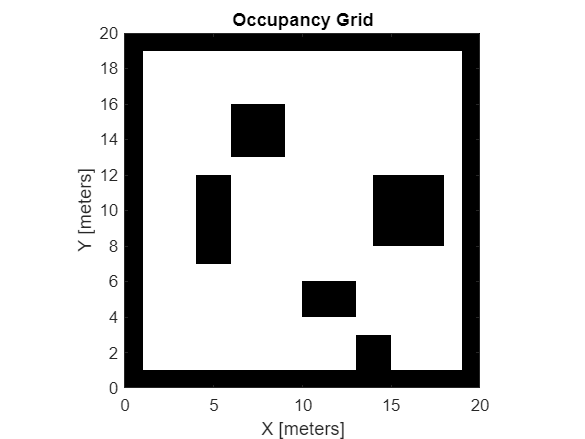

Map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0  

omap =   occupancyMap with properties:

   mapLayer Properties
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
                LayerName: 'probabilityLayer'
                 DataType: 'double'
             DefaultValue: 0.5000
      GridLocationInWorld: [0 0]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]
               Resolution: 1
                 GridSize: [20 20]
             XLocalLimits: [0 20]
             YLocalLimits: [0 20]
             XWorldLimits: [0 20]
             YWorldLimits: [0 20]


Map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     0     0     0     0     0     0     0     0     0     0     1     1     1     0     0     0     0     1
     1     0     0     0     0     0     0     0     1     1     0     0     1     1     1     0     0     0     0     1
     1     0     0     0     0     0     0     0     1     1     0     0     1     1     1     0     0     0     0     1
     1     0     0     0     0     0     0     0     1     1     0     0     1     1     1     0     0     0     0     1
     1     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0  

omap =   occupancyMap with properties:

   mapLayer Properties
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
                LayerName: 'probabilityLayer'
                 DataType: 'double'
             DefaultValue: 0.5000
      GridLocationInWorld: [0 0]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]
               Resolution: 1
                 GridSize: [20 20]
             XLocalLimits: [0 20]
             YLocalLimits: [0 20]
             XWorldLimits: [0 20]
             YWorldLimits: [0 20]


Map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     1     1     1     1     1     0     0     0     0     1
     1     0     0     0  

omap =   occupancyMap with properties:

   mapLayer Properties
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
                LayerName: 'probabilityLayer'
                 DataType: 'double'
             DefaultValue: 0.5000
      GridLocationInWorld: [0 0]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]
               Resolution: 1
                 GridSize: [20 20]
             XLocalLimits: [0 20]
             YLocalLimits: [0 20]
             XWorldLimits: [0 20]
             YWorldLimits: [0 20]


Map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     1     0     0     0  

omap =   occupancyMap with properties:

   mapLayer Properties
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
                LayerName: 'probabilityLayer'
                 DataType: 'double'
             DefaultValue: 0.5000
      GridLocationInWorld: [0 0]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]
               Resolution: 1
                 GridSize: [20 20]
             XLocalLimits: [0 20]
             YLocalLimits: [0 20]
             XWorldLimits: [0 20]
             YWorldLimits: [0 20]


Map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     1     1     1     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     1     1     1     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0  

omap =   occupancyMap with properties:

   mapLayer Properties
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
                LayerName: 'probabilityLayer'
                 DataType: 'double'
             DefaultValue: 0.5000
      GridLocationInWorld: [0 0]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]
               Resolution: 1
                 GridSize: [20 20]
             XLocalLimits: [0 20]
             YLocalLimits: [0 20]
             XWorldLimits: [0 20]
             YWorldLimits: [0 20]



    %12 akadály lesz itt is
    numberofObs = 0;
    RequiredObs = 5;
    while RequiredObs ~= numberofObs
    

   %Ez 1 és 50 között generál nekünk értékeke
   %Ami egy scalarként van visszaadva (Mivel 1 van a vektor után írva, de
   %ott lehetne több érték is pl randi([-5, 5], 10, 1) Ezzel egy 10 soros
   %oszlopvektort hoz létre -5 és 5 közötti számokkal
        width = randi([1 4], 1);
        length = randi([1 4], 1);

        xPosition = randi([1 mapWidth - width], 1);
        yPosition = randi([1 mapLength - length], 1);


        [xobstacle, yobstacle] = meshgrid(xPosition:xPosition+width, yPosition:yPosition+length);
        xyzObs = [xobstacle(:) yobstacle(:)];

        checkIntersection =false;
        for i = 1:size(xyzObs, 1)
            if checkOccupancy(omap, xyzObs(i,:)) == 1
                checkIntersection = true;
                break
            end
        end
    
        if ~checkIntersection
            for i = 1:size(xyzObs,1)
                Map(xyzObs(i,2), xyzObs(i,1)) = 1;
            end
            setOccupancy(omap, xyzObs, 1);
            numberofObs = numberofObs+1;
        end
    end


    Map
    show(omap)
    omap
    save("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map" + j + ".mat", "omap");
    save("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map_data"+j+".mat", "Map")

end